clear
%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt, false);

%順運動学
for angle = 0 : pi/10 : 2*pi
    robot = robot.setJointThetas([angle; angle; 0]);
    robot = robot.updateRobotState;
    robot.plotRobot;

    drawnow; 
end

clear
%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt, false);

%逆運動学
theta = 0;
path_num = 2;
for t = 0 : dt : 3
    theta = theta + pi * dt;
    path_num = path_num - 0.3 * dt;
    robot = robot.setPosition([path_num; 0.5*sin(theta); 0]);
    robot = robot.setOrientation(0);
    robot = robot.calcInverseKinematics;
    robot = robot.updateRobotState;
    
    robot.plotRobot;

    drawnow; 
end


clear
%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt, false);

%ヤコビアン
for t = 0 : dt : 1
    robot = robot.calcInverseKinematicsUsingJacobian([-1; 0], 0); %単位：[m/s, m/s], rad/s
    robot = robot.updateRobotState;
    
    robot.plotRobot;

    drawnow; 
end


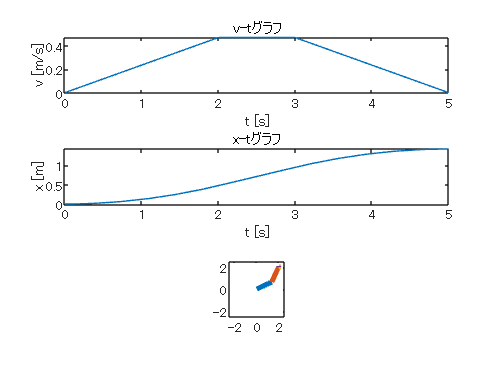

clear
%初期化
dt = 0.05;
robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1.5; 1.5], dt, true);

%軌道生成
run("path_3DOF_2D.m");

%軌道追従（逆運動学）
time = 0 : dt : T_f_;
path_num = 1 + double(path);

idx = 0;
for t = time
    idx = idx + 1;
    robot = robot.setPosition([path_num(1, idx); path_num(2, idx); 0]);
    robot = robot.setOrientation(0);
    robot = robot.calcInverseKinematics;
    robot = robot.updateRobotState;
    
    robot.plotRobot;

    drawnow; 
end